original = zeros(128,128);

% Build a fan
% gFan = buildFan(original,0);


Target

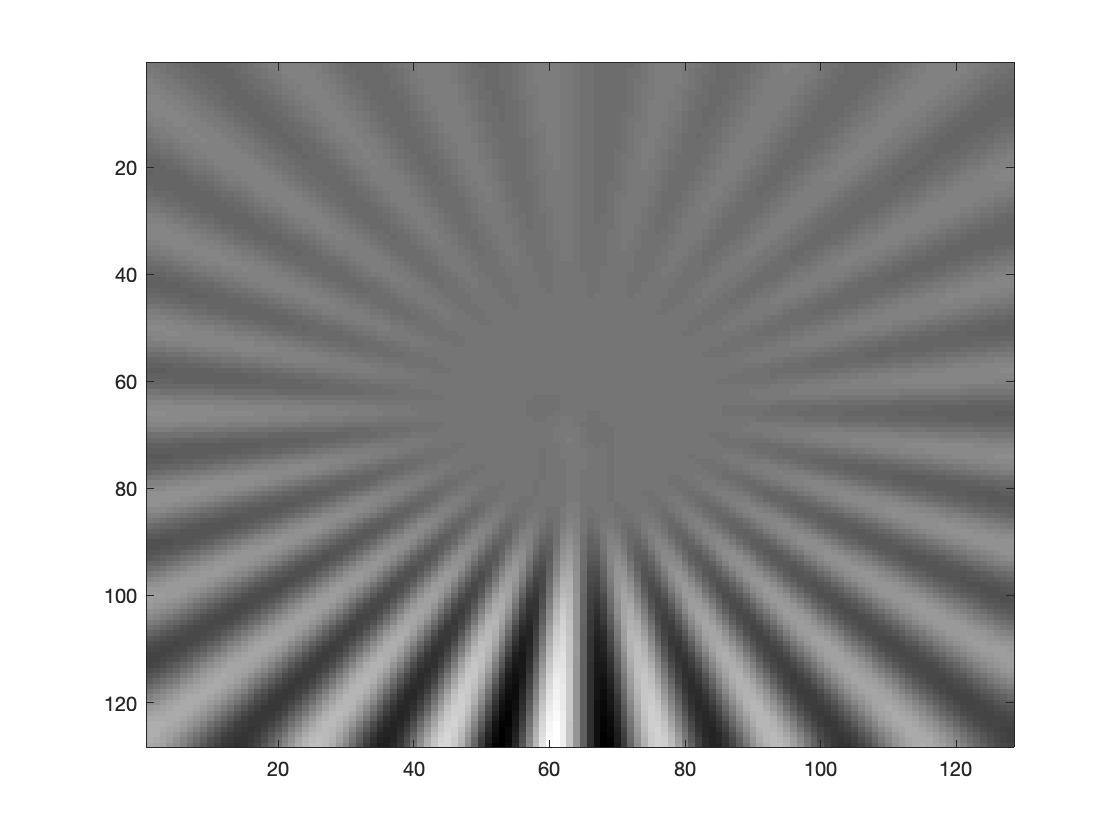

A=1; B=0; sd = 2; k = 4;
correct_angle = 0.25/k;

target = buildFan(original,correct_angle);
blurred = imgaussfilt(target,sd);
target = blurred*A + B;
imagesc(target); colormap('gray');

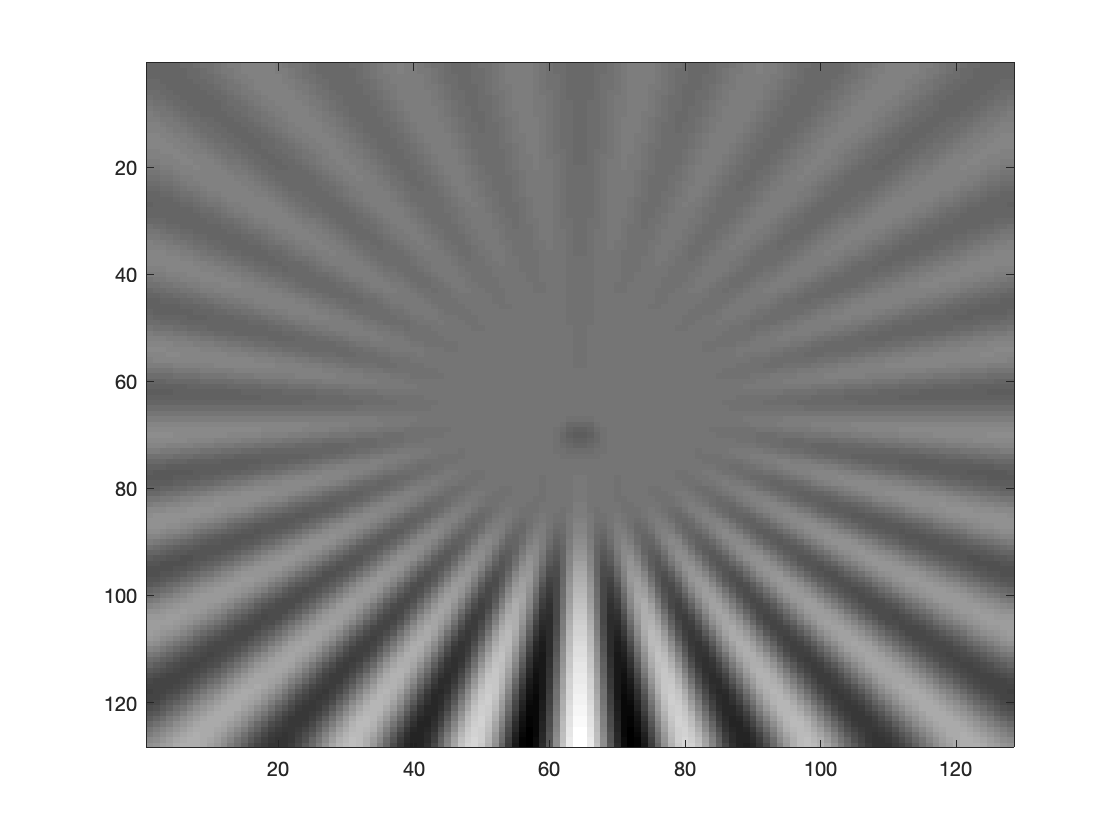


ref_img = buildFan(original,0);
ref_img = imgaussfilt(ref_img, sd) * A + B;
original_ref = imgaussfilt(ref_img, sd) * A + B;
imagesc(ref_img); colormap('gray');

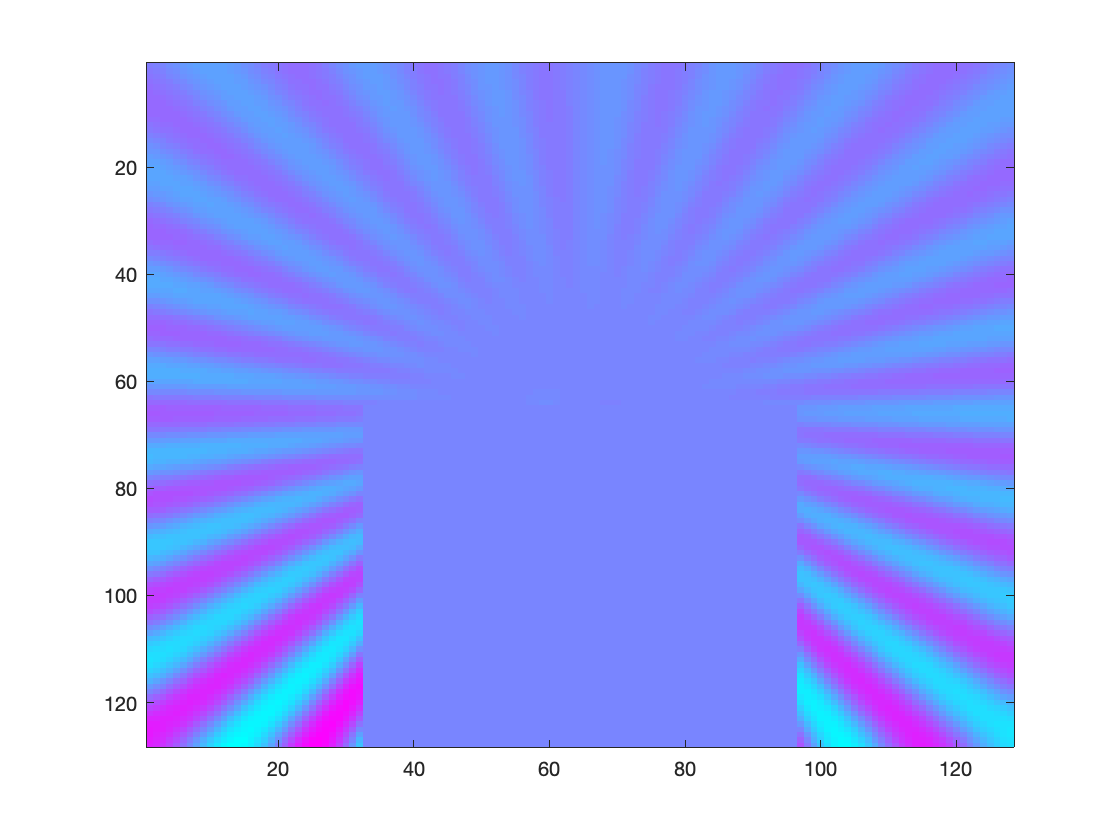


% test = target;
% test(128/2+1:end, 128/4+1:3*128/4) = 0;
% imagesc(test);colormap('cool')

Calculating tmetric measures

start = -0.2; stop = 0.2;
% For every 0.0025 of a radian degree
step_size = 0.01/4;
thetas = start:step_size:stop;
[metric_vals, local_max] = getMetrics(target,ref_img, thetas, A, B);

idx = 6

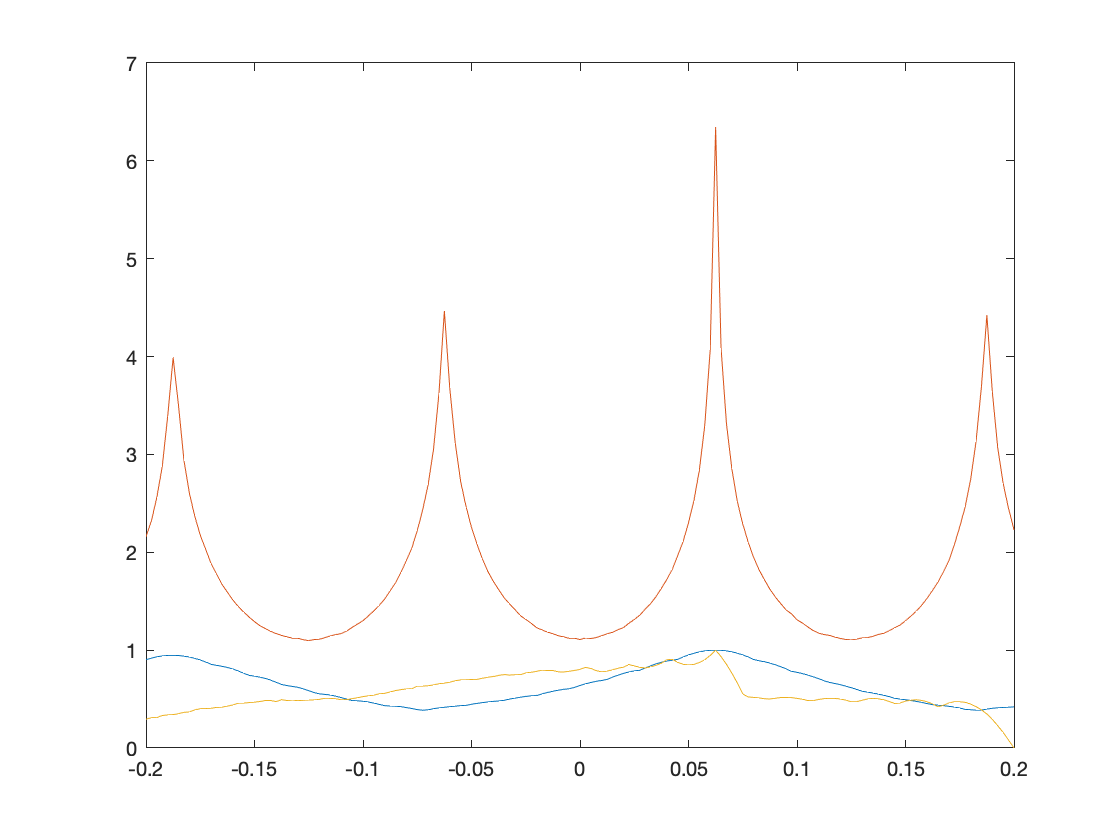


ncc = metric_vals(1,:);
mutual_inf = metric_vals(2,:);
qf_dist = metric_vals(3,:);


plot(thetas, ncc);
hold on;
plot(thetas, mutual_inf);
plot(thetas, qf_dist);
hold off;

Evaluating metrics

[metric_max max_idx] = max(ncc);
max_angle = thetas(max_idx)

max_angle = 0.0625




accuracy = max_angle/correct_angle * 100

accuracy = 100

relative_diff = (metric_max - local_max(1)) / metric_max

relative_diff = 0.0528

smooth_fn = polyfit( thetas(max_idx-2:max_idx+2), metric_vals(max_idx-2:max_idx+2), 2);

% Peakiness = Negative 2nd derivative = -2 * first term of 2nd order polynomial
peakiness = -2*smooth_fn(1)

peakiness = -1.3052e+04

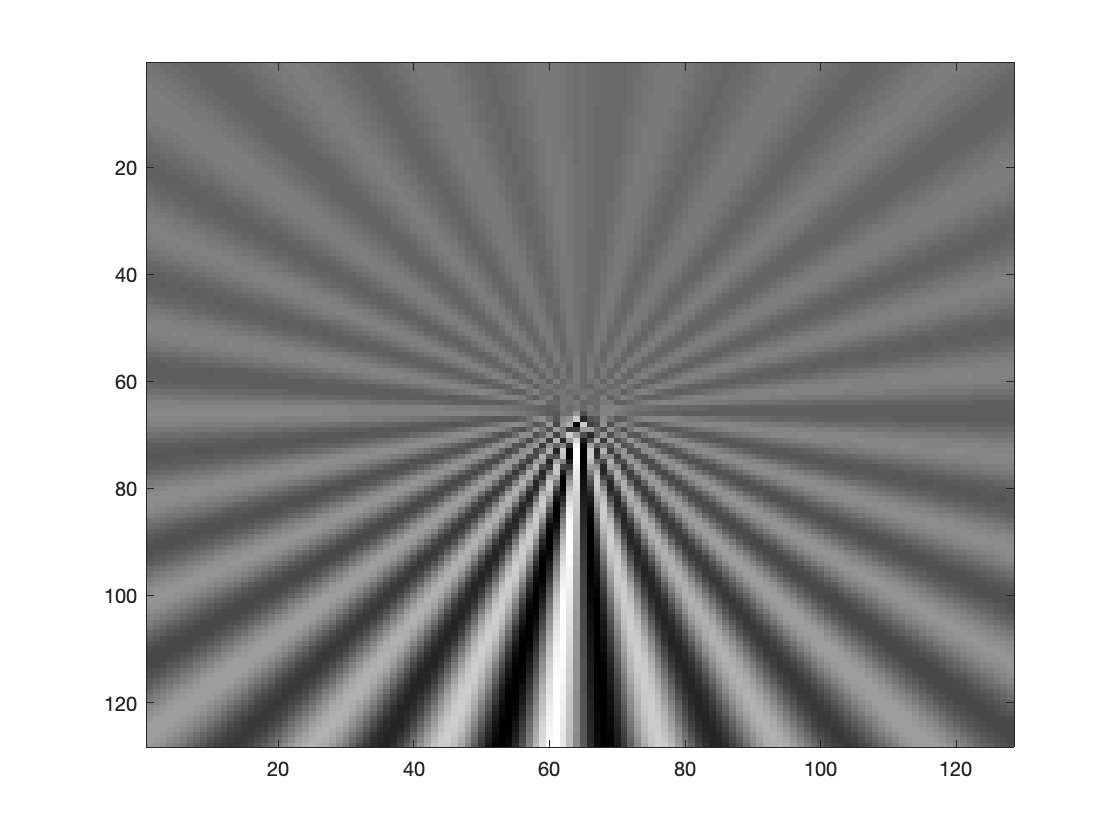


final_img = buildFan(original_ref, max_angle);
imagesc(final_img); colormap('gray')

[metric_max max_idx] = max(mutual_inf);
max_angle = thetas(max_idx)

max_angle = 0.0625


accuracy = max_angle/correct_angle * 100

accuracy = 100

relative_diff = (metric_max - local_max(2)) / metric_max

relative_diff = 0.3708

smooth_fn = polyfit( thetas(max_idx-1:max_idx+1), metric_vals(max_idx-1:max_idx+1), 2);

% Peakiness = Negative 2nd derivative = -2 * first term of 2nd order polynomial
peakiness = -2*smooth_fn(1)

peakiness = -9.7134e+04


final_img = buildFan(original_ref, max_angle);
imagesc(final_img); colormap('gray')

[metric_max max_idx] = max(qf_dist);
max_angle = thetas(max_idx)

max_angle = 0.0625


accuracy = max_angle/correct_angle * 100

accuracy = 100

relative_diff = (metric_max - local_max(3)) / metric_max

relative_diff = 0.6591

smooth_fn = polyfit( thetas(max_idx-2:max_idx+2), metric_vals(max_idx-2:max_idx+2), 2);

% Peakiness = Negative 2nd derivative = -2 * first term of 2nd order polynomial
peakiness = -2*smooth_fn(1)

peakiness = -1.3052e+04


final_img = buildFan(original_ref, max_angle);
imagesc(final_img); colormap('gray')






% pcolor(ncc); colormap('autumn')


% metric1 = (m_max -m_lower)/m_max
% metric2 = -ve 2nd derivative / m_max

% finitew derivative second derivative

% decide a regon for the quantile function
% get a histogram in that region
% make it into a quantile function
% we do it for both target and reference
% comparison b/w quantile fucntions = euclidean dist
% has to be able to worlk even when intensities are flipped - could work